clear
syms x y
Circ1=x^2+y^2==4

$$Circ1 = x^{2}+y^{2}=4$$

A=sym([-2 0])

$$A = \left(\begin{array}{cc} -2 & 0 \end{array}\right)$$

hold on
fimplicit(Circ1)
plot(A(1),A(2),'ro')
grid
syms k
Lk=linekp(k,A)

$$Lk = y=k\,\left(x+2\right)$$

Sol=solve([Circ1,Lk],[x y])

Sol = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


B=[Sol.x(2) Sol.y(2)]

$$B = \left(\begin{array}{cc} -\frac{2\,\left(k^{2}-1\right)}{k^{2}+1} & \frac{4\,k}{k^{2}+1} \end{array}\right)$$

M=divseg2(A,B,-2)

$$M = \left(\begin{array}{cc} 2-\frac{4\,\left(k^{2}-1\right)}{k^{2}+1} & \frac{8\,k}{k^{2}+1} \end{array}\right)$$

k1=-10:0.1:10;
X(k)=M(1)

$$X(k) = 2-\frac{4\,\left(k^{2}-1\right)}{k^{2}+1}$$

Y(k)=M(2)

$$Y(k) = \frac{8\,k}{k^{2}+1}$$

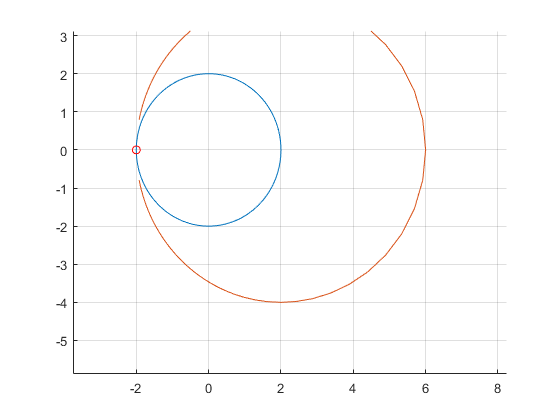

X1=X(k1);
Y1=Y(k1);
plot(X1,Y1)

xlim([-3.75 8.25])
ylim([-5.88 3.12])

eq1=x-X(k)

$$eq1 = x+\frac{4\,\left(k^{2}-1\right)}{k^{2}+1}-2$$

eq1=simplify(subs(eq1,k,y/(x+2)))

$$eq1 = -\frac{\left(x+2\right)\,\left(-x^{2}+4\,x-y^{2}+12\right)}{x^{2}+4\,x+y^{2}+4}$$

eq1=x^2+y^2-4*x-12

$$eq1 = x^{2}-4\,x+y^{2}-12$$

eq1=(x-2)^2+y^2==16

$$eq1 = {\left(x-2\right)}^{2}+y^{2}=16$$